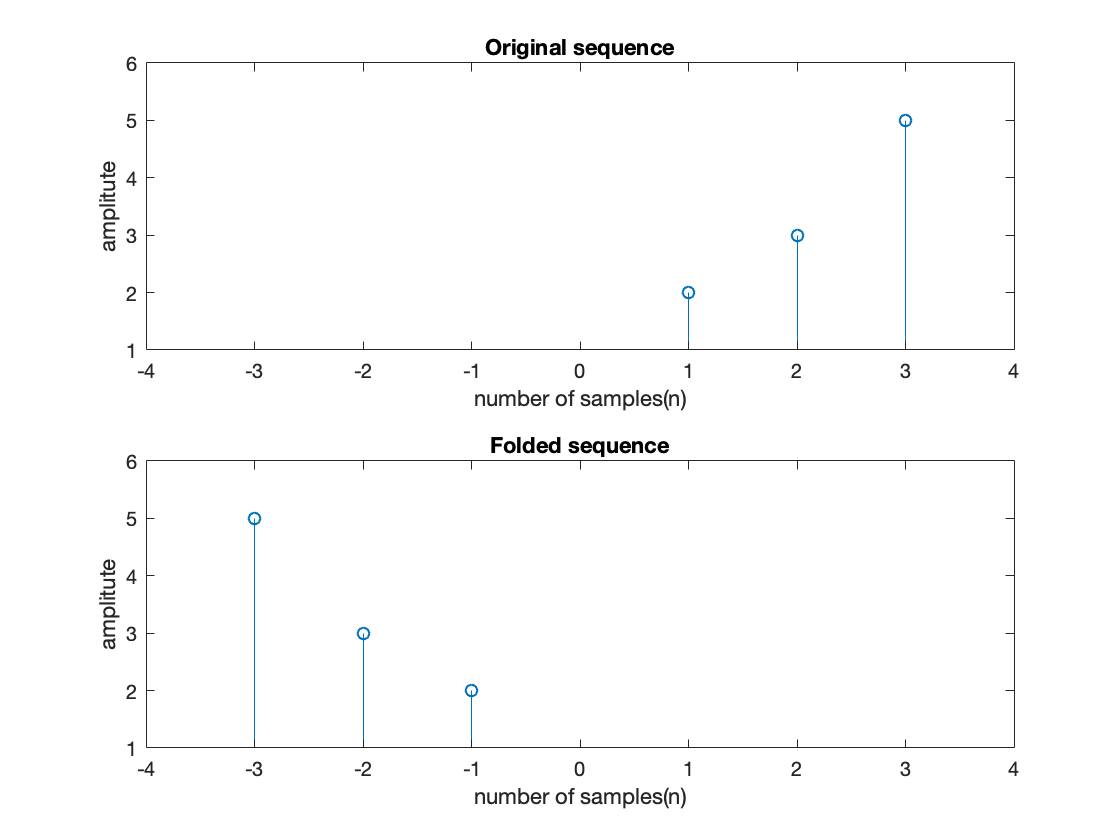

%----------------------------------------------------------------------
%Name : Sumit Patidar
%Roll no: B15237
%Task : program to fold sequence 
%----------------------------------------------------------------------

close all;
clc;

%take sequence as an input
%I am assuming sequence starts from n = 1
seq = input('enter the sequence: '); %example input = [1 2 3 4 5]
seq_length = length(seq);
n = 1:1:seq_length;

%plot given sequence
p1 = subplot(2,1,1);
stem(n, seq);
xlabel('number of samples(n)');
ylabel('amplitute');
title('Original sequence');
hold on;

%fold sequence and then plot the new sequence
folded_seq = seq(seq_length-n+1); %reversing sequence
new_n = -seq_length:1:-1;
p2 = subplot(2,1,2);
stem(new_n, folded_seq);
xlabel('number of samples(n)');
ylabel('amplitute');
title('Folded sequence');

%setting axis limits to visualize better
axis([p1 p2], [-seq_length-1 seq_length+1 min(seq)-1 max(seq)+1]);